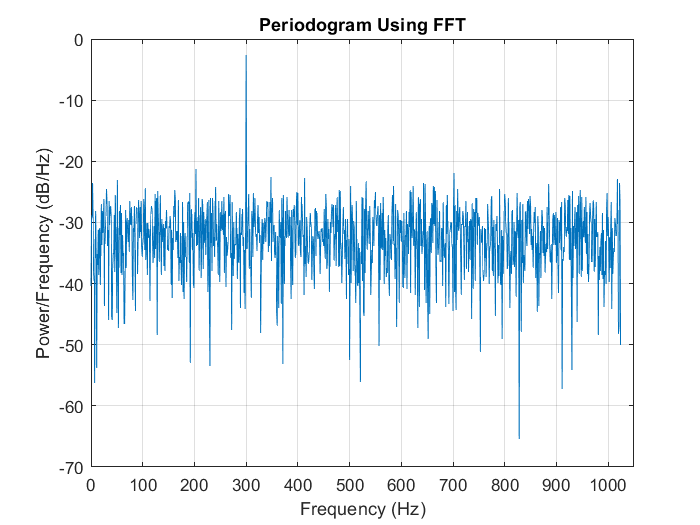

Fs = 2048;
t = 0:1/Fs:1-1/Fs;
x = sin(2*pi*t*300) + randn(size(t));
N = length(x);
xdft = fft(x);
xdft = xdft(1:N/2+1);
psdx = (1/(Fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:Fs/length(x):Fs/2;

plot(freq,10*log10(psdx))
xlim([0 1050])
grid on
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')